Functional Evaluation

We want to evaluate the function


$$y(t) = 1 - \frac{e^{-0.3(2)t}}{\sqrt{1 - 0.3^2}} 
        \sin\!\left(2\sqrt{1 - 0.3^2}\,t + 
        \tan^{-1}\!\frac{\sqrt{1 - 0.3^2}}{0.3}\right)$$


for an array of values of $t$.

First, Create a vector of length `N` with time values between 0-10 s.

N = 25;
tt = linspace(0,10,N);

Then, using [array (element-wise) operations,](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html) evaluate the function for each element in `tt` and store the results in a new vector called `yy`.

zeta = 0.3;
wn = 2;
wd = wn*sqrt(1 - zeta^2);
phi = atan(sqrt(1 - zeta^2)/zeta);
yy = 1 - exp(-zeta*wn*tt)./sqrt(1 - zeta^2)...
    .*sin(wd*tt + phi);


To visualize the function, plot the `N` descrete 2D points.

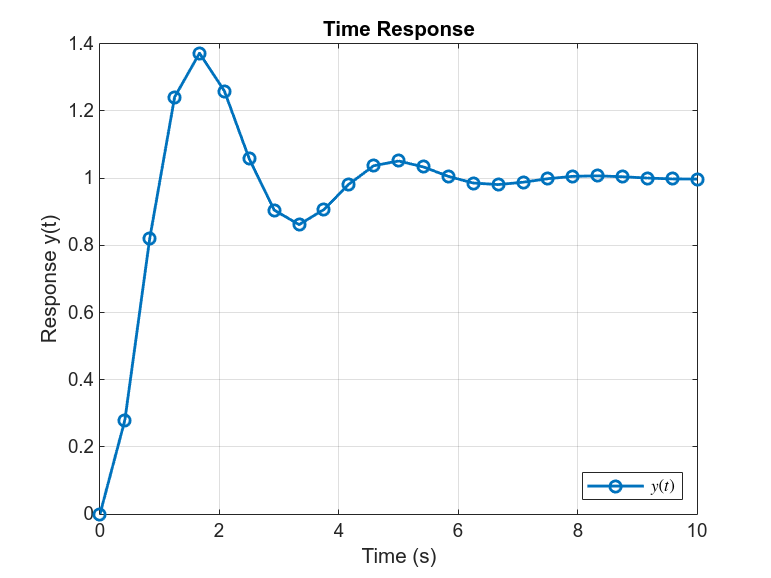

figure(1);
clf()
plot(tt, yy, '-o', ...
    'LineWidth', 1.5, ...
    'DisplayName', '$y(t)$')
xlabel('Time (s)')
ylabel('Response y(t)')
title('Time Response')
grid on
legend('location', 'southeast', 'Interpreter','latex')

### Find the interval of time for which $y(t) \geq 1.2$

First, we can use comparison operators to do element-wise comparison.  This command will generate a vector of length `N`, the same length as `tt`, with each element the result of the comparison:

comparison_vector = (yy >= 1.2)

comparison_vector = 1×25 logical array
   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


Next we can find the indices of that comparison vector that are true (1).  This command returns a vector of all the indices for which the comparison is true.

indices = find(yy >= 1.2)

indices =      4     5     6


Because the vectors `tt` and `yy` contain corresponding elements, we can use the indices to find the times that correspond to the comparison:

fprintf("From t = %4.2f to %4.2f, the values of y(t) are >= 1.2 \n", ...
    tt(indices(1)), tt(indices(end)));

From t = 1.25 to 2.08, the values of y(t) are >= 1.2 


We can then add new markers to only that subset of the vectors...

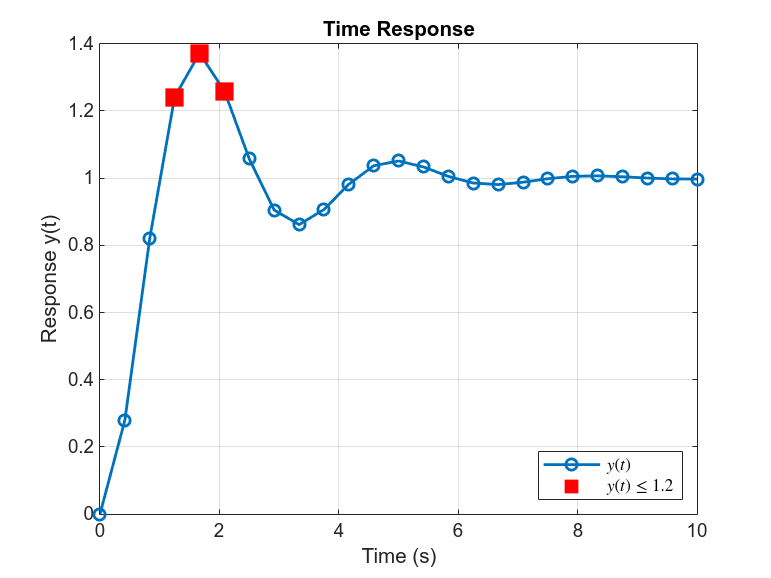

hold on
plot(tt(indices), yy(indices), 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r',...
    'DisplayName',"$y(t) \leq 1.2$")

### Find the Rise Time

**Rise time** is the time it takes for a system’s step response to go from 10% to 90% of its final steady-state value.

Let's start by finding all the values of the response that are great than 10% of the final value:

indices = find(yy >= 0.10*yy(end));

We can use the **first index **from indices to lookup the corresponding time value

t10 = tt(indices(1));
plot(tt(indices(1)), yy(indices(1)), 'go', 'MarkerSize',14, ...
    'DisplayName', 't10')

Next we can find the index of the first value of `yy` that is larger than 90% of the final value.  We can use the optional, second argument to the [`find(X,n)`](https://www.mathworks.com/help/matlab/ref/find.html) function to return the first element of the comparision array.

ii = find(yy >= 0.90*yy(end), 1);
t90 = tt(ii);
plot(tt(ii), yy(ii), 'ro', 'MarkerSize',14, ...
    'DisplayName', 't90')

We can estimate the *rise time:*

Tr = t90-t10

Tr = 0.8333

Because we used a coarse sampling of the function $y(t)$ - we only evaluated the function at `N=25` values for time, the estimate is not terribly accurate.  To increase the accuracy we can sample $t$ and $y(t)$ more densely. 

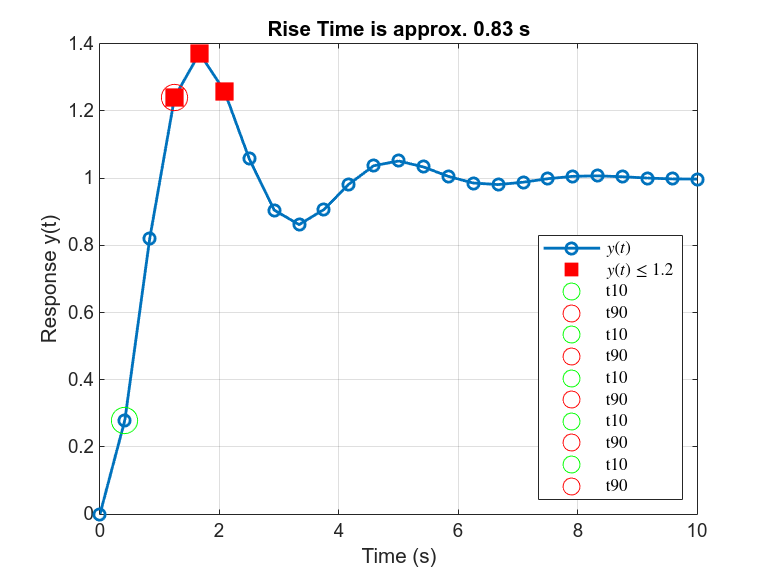

title(sprintf("Rise Time is approx. %.2f s", Tr))